clc
clear
close all

LU31_mm_to_liter = 40.4/(267-114)

LU31_mm_to_liter = 0.2641

LU31_efective_capacity = LU31_mm_to_liter*(600-50)

LU31_efective_capacity = 145.2288


LU34_mm_to_liter = 40.4/(391-239)

LU34_mm_to_liter = 0.2658

LU34_efective_capacity = LU34_mm_to_liter*(600-50)

LU34_efective_capacity = 146.1842


LU41_outer_mm_to_liter = 45.3/(438-249)

LU41_outer_mm_to_liter = 0.2397

LU41_outer_efective_capacity = LU41_outer_mm_to_liter*(560-112)

LU41_outer_efective_capacity = 107.3778

LU41_inner_mm_to_liter = pi*((23.25/2)*10)^2*0.000001

LU41_inner_mm_to_liter = 0.0425

LU41_inner_efective_capacity = LU41_inner_mm_to_liter*(510-150)

LU41_inner_efective_capacity = 15.2840


LU43_outer_mm_to_liter = 40.4/(397-212)

LU43_outer_mm_to_liter = 0.2184

LU43_outer_efective_capacity = LU43_outer_mm_to_liter*(560-60)

LU43_outer_efective_capacity = 109.1892

LU43_inner_mm_to_liter = pi*((23.3/2)*10)^2*0.000001

LU43_inner_mm_to_liter = 0.0426

LU43_inner_efective_capacity = LU43_inner_mm_to_liter*(703-150)

LU43_inner_efective_capacity = 23.5791



LU44_outer_mm_to_liter = 40.4/(376-196)

LU44_outer_mm_to_liter = 0.2244

LU44_outer_efective_capacity = LU44_outer_mm_to_liter*(560-93)

LU44_outer_efective_capacity = 104.8156

LU44_inner_mm_to_liter = pi*((24.5/2)*10)^2*0.000001

LU44_inner_mm_to_liter = 0.0471

LU44_inner_efective_capacity = LU44_inner_mm_to_liter*(695-150)

LU44_inner_efective_capacity = 25.6932


file = load("C:\Users\frede\Desktop\Final tests\Prototype system test\test 3. input&output\Rain scenario simulation\Concentrated cloud burst\Out 5\Test 1\Results.mat")

file = struct with fields:
    data: [1×1 Simulink.SimulationData.Dataset]


data = file.data

data = Simulink.SimulationData.Dataset 'data' with 11 elements

                         Name            PropagatedName  BlockPath                                
                         ______________  ______________  ________________________________________ 
    1  [1x1 Signal]      Bus Creator6    Bus Creator6    valveWithHighResCommands/31 data        
    2  [1x1 Signal]      Bus Creator7    Bus Creator7    valveWithHighResCommands/34 data        
    3  [1x1 Signal]      control 41      control 41      ...HighResCommands/Flow and control LU41
    4  [1x1 Signal]      control 43      control 43      ...HighResCommands/Flow and control LU43
    5  [1x1 Signal]      control 44      control 44      ...HighResCommands/Flow and control LU44
    6  [1x1 Si

Names = data.getElementNames

Names = 11×1 cell array
    {'Bus↵Creator6'  }
    {'Bus↵Creator7'  }
    {'control 41'    }
    {'control 43'    }
    {'control 44'    }
    {'Controller:4'  }
    {'Tank 44 data'  }
    {'Valve openings'}
    {'source_flows'  }
    {'Tank 41 data'  }
    {'Tank 43 data'  }


numberOfPlots = 5

numberOfPlots = 5

PlotFontSize = 8

PlotFontSize = 8

LegendFontSize = 7

LegendFontSize = 7

PlotThickness = 1.3

PlotThickness = 1.3000

LU41Color = "#0072bd"

LU41Color = "#0072bd"

LU43Color = "#edb120"

LU43Color = "#edb120"

LU44Color = "#fe330a"

LU44Color = "#fe330a"

Xspan = [0 400]

Xspan =      0   400



RemainingCapacityIndex = find(strcmp(Names,'Controller:4'),1) %7

RemainingCapacityIndex = 6

ValveOpeningsIndex = find(strcmp(Names,'Valve openings'),1)

ValveOpeningsIndex = 8

SorceflowIndex = find(strcmp(Names,'source_flows'),1) %10

SorceflowIndex = 9

LU41Index = find(strcmp(Names,'Tank 41 data'),1) %11

LU41Index = 10

LU43Index = find(strcmp(Names,'Tank 43 data'),1) %12

LU43Index = 11

LU44Index = find(strcmp(Names,'Tank 44 data'),1) %8

LU44Index = 7

LU41ControlerIndex = find(strcmp(Names,'control 41'),1) %3

LU41ControlerIndex = 3

LU43ControlerIndex = find(strcmp(Names,'control 43'),1) %4

LU43ControlerIndex = 4

LU44ControlerIndex = find(strcmp(Names,'control 44'),1) %5

LU44ControlerIndex = 5



fig = figure;
set(fig, "Units", "pixels", "Position", [100 100 600 550]);

subplot(numberOfPlots,1,1)
% Pick the data 
LU43Controller_data = data.getElement(LU43ControlerIndex)

LU43Controller_data =   Simulink.SimulationData.Signal
  Package: Simulink.SimulationData

  Properties:
              Name: 'control 43'
    PropagatedName: 'control 43'
         BlockPath: [1×1 Simulink.SimulationData.BlockPath]
          PortType: 'inport'
         PortIndex: 1
            Values: [1×1 struct]


  Methods, Superclasses

LU44Controller_data = data.getElement(LU44ControlerIndex)

LU44Controller_data =   Simulink.SimulationData.Signal
  Package: Simulink.SimulationData

  Properties:
              Name: 'control 44'
    PropagatedName: 'control 44'
         BlockPath: [1×1 Simulink.SimulationData.BlockPath]
          PortType: 'inport'
         PortIndex: 1
            Values: [1×1 struct]


  Methods, Superclasses

LU43Controller_values = LU43Controller_data.Values

LU43Controller_values = struct with fields:
                    signal1: [1×1 timeseries]
    Total_supplied__to_LU43: [1×1 timeseries]
                    signal3: [1×1 struct]


LU44Controller_values = LU44Controller_data.Values

LU44Controller_values = struct with fields:
                         u: [1×1 timeseries]
    Total_supplied_to_LU44: [1×1 timeseries]
                   signal3: [1×1 struct]


hold("on")
ax = gca;
ax.FontSize = PlotFontSize;        % tick labels
title("Rain profile for scenario 1","FontSize", PlotFontSize)
ylabel({"Flow rate"; "(liters/minute)"},"FontSize", PlotFontSize)
ylim([-1 25])
xlim(Xspan)
grid on
plot(LU43Controller_values.signal3.signal1,"color",LU43Color,"linewidth",PlotThickness)
plot(LU44Controller_values.signal3.signal1,"color",LU44Color,"linewidth",PlotThickness)
legend("LU43","LU44","location","eastoutside","FontSize", LegendFontSize)
hold("off")


file = load("C:\Users\frede\Desktop\Final tests\Prototype system test\test 3. input&output\Rain scenario simulation\Moving intense rain\Out5\Test 1\Results.mat")

file = struct with fields:
    data: [1×1 Simulink.SimulationData.Dataset]


data = file.data

data = Simulink.SimulationData.Dataset 'data' with 11 elements

                         Name            PropagatedName  BlockPath                                
                         ______________  ______________  ________________________________________ 
    1  [1x1 Signal]      Bus Creator6    Bus Creator6    valveWithHighResCommands/31 data        
    2  [1x1 Signal]      Bus Creator7    Bus Creator7    valveWithHighResCommands/34 data        
    3  [1x1 Signal]      control 41      control 41      ...HighResCommands/Flow and control LU41
    4  [1x1 Signal]      control 43      control 43      ...HighResCommands/Flow and control LU43
    5  [1x1 Signal]      control 44      control 44      ...HighResCommands/Flow and control LU44
    6  [1x1 Si

Names = data.getElementNames

Names = 11×1 cell array
    {'Bus↵Creator6'  }
    {'Bus↵Creator7'  }
    {'control 41'    }
    {'control 43'    }
    {'control 44'    }
    {'Controller:4'  }
    {'Tank 44 data'  }
    {'Valve openings'}
    {'source_flows'  }
    {'Tank 41 data'  }
    {'Tank 43 data'  }


LU43ControlerIndex = find(strcmp(Names,'control 43'),1) %4

LU43ControlerIndex = 4

LU44ControlerIndex = find(strcmp(Names,'control 44'),1) %5

LU44ControlerIndex = 5


subplot(numberOfPlots,1,2)
% Pick the data 
LU43Controller_data = data.getElement(LU43ControlerIndex)

LU43Controller_data =   Simulink.SimulationData.Signal
  Package: Simulink.SimulationData

  Properties:
              Name: 'control 43'
    PropagatedName: 'control 43'
         BlockPath: [1×1 Simulink.SimulationData.BlockPath]
          PortType: 'inport'
         PortIndex: 1
            Values: [1×1 struct]


  Methods, Superclasses

LU44Controller_data = data.getElement(LU44ControlerIndex)

LU44Controller_data =   Simulink.SimulationData.Signal
  Package: Simulink.SimulationData

  Properties:
              Name: 'control 44'
    PropagatedName: 'control 44'
         BlockPath: [1×1 Simulink.SimulationData.BlockPath]
          PortType: 'inport'
         PortIndex: 1
            Values: [1×1 struct]


  Methods, Superclasses

LU43Controller_values = LU43Controller_data.Values

LU43Controller_values = struct with fields:
                    signal1: [1×1 timeseries]
    Total_supplied__to_LU43: [1×1 timeseries]
                    signal3: [1×1 struct]


LU44Controller_values = LU44Controller_data.Values

LU44Controller_values = struct with fields:
                         u: [1×1 timeseries]
    Total_supplied_to_LU44: [1×1 timeseries]
                   signal3: [1×1 struct]


hold("on")
ax = gca;
ax.FontSize = PlotFontSize;        % tick labels
title("Rain profile for scenario 2","FontSize", PlotFontSize)
ylabel({"Flow rate"; "(liters/minute)"},"FontSize", PlotFontSize)
ylim([-1 25])
xlim(Xspan)
grid on
plot(LU43Controller_values.signal3.signal1,"color",LU43Color,"linewidth",PlotThickness)
plot(LU44Controller_values.signal3.signal1,"color",LU44Color,"linewidth",PlotThickness)
legend("LU43","LU44","location","eastoutside","FontSize", LegendFontSize)
hold("off")


file = load("C:\Users\frede\Desktop\Final tests\Prototype system test\test 3. input&output\Rain scenario simulation\Intensefying rain\Out5\Test 1\Results.mat")

file = struct with fields:
    data: [1×1 Simulink.SimulationData.Dataset]


data = file.data

data = Simulink.SimulationData.Dataset 'data' with 11 elements

                         Name            PropagatedName  BlockPath                                
                         ______________  ______________  ________________________________________ 
    1  [1x1 Signal]      Bus Creator6    Bus Creator6    valveWithHighResCommands/31 data        
    2  [1x1 Signal]      Bus Creator7    Bus Creator7    valveWithHighResCommands/34 data        
    3  [1x1 Signal]      control 41      control 41      ...HighResCommands/Flow and control LU41
    4  [1x1 Signal]      control 43      control 43      ...HighResCommands/Flow and control LU43
    5  [1x1 Signal]      control 44      control 44      ...HighResCommands/Flow and control LU44
    6  [1x1 Si

Names = data.getElementNames

Names = 11×1 cell array
    {'Bus↵Creator6'  }
    {'Bus↵Creator7'  }
    {'control 41'    }
    {'control 43'    }
    {'control 44'    }
    {'Controller:4'  }
    {'Tank 44 data'  }
    {'Valve openings'}
    {'source_flows'  }
    {'Tank 41 data'  }
    {'Tank 43 data'  }


LU43ControlerIndex = find(strcmp(Names,'control 43'),1) %4

LU43ControlerIndex = 4

LU44ControlerIndex = find(strcmp(Names,'control 44'),1) %5

LU44ControlerIndex = 5


subplot(numberOfPlots,1,3)
% Pick the data 
LU43Controller_data = data.getElement(LU43ControlerIndex)

LU43Controller_data =   Simulink.SimulationData.Signal
  Package: Simulink.SimulationData

  Properties:
              Name: 'control 43'
    PropagatedName: 'control 43'
         BlockPath: [1×1 Simulink.SimulationData.BlockPath]
          PortType: 'inport'
         PortIndex: 1
            Values: [1×1 struct]


  Methods, Superclasses

LU44Controller_data = data.getElement(LU44ControlerIndex)

LU44Controller_data =   Simulink.SimulationData.Signal
  Package: Simulink.SimulationData

  Properties:
              Name: 'control 44'
    PropagatedName: 'control 44'
         BlockPath: [1×1 Simulink.SimulationData.BlockPath]
          PortType: 'inport'
         PortIndex: 1
            Values: [1×1 struct]


  Methods, Superclasses

LU43Controller_values = LU43Controller_data.Values

LU43Controller_values = struct with fields:
                    signal1: [1×1 timeseries]
    Total_supplied__to_LU43: [1×1 timeseries]
                    signal3: [1×1 struct]


LU44Controller_values = LU44Controller_data.Values

LU44Controller_values = struct with fields:
                         u: [1×1 timeseries]
    Total_supplied_to_LU44: [1×1 timeseries]
                   signal3: [1×1 struct]


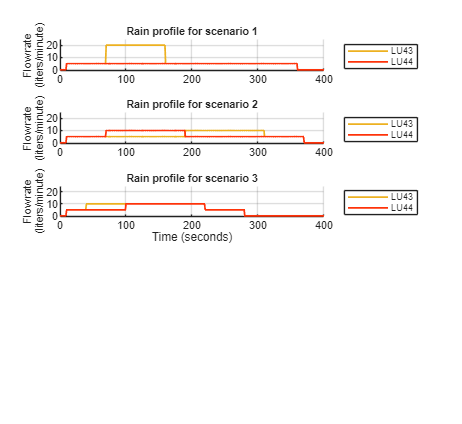

hold("on")
ax = gca;
ax.FontSize = PlotFontSize;        % tick labels
title("Rain profile for scenario 3","FontSize", PlotFontSize)
ylabel({"Flow rate"; "(liters/minute)"},"FontSize", PlotFontSize)
ylim([-1 25])
xlim(Xspan)
xlabel("Time (seconds)")
grid on
plot(LU43Controller_values.signal3.signal1,"color",LU43Color,"linewidth",PlotThickness)
plot(LU44Controller_values.signal3.signal1,"color",LU44Color,"linewidth",PlotThickness)
legend("LU43","LU44","location","eastoutside","FontSize", LegendFontSize)
hold("off")